m_cart = 0.493;
m_pend = 0.312;
I_pend = 0.00024;
l = 0.04;
f = 0.01;
k_T = 0.11;
R = 10;
r = 0.0335;
g = 9.8;

d = 0.165;
Iw = 0.00002805*3;
Ip = 0.001972;
Ts = 0.005;


A = [-(I_pend+m_pend*(l^2))*f/(I_pend*(m_cart+m_pend)+m_cart*m_pend*(l^2)) (m_pend^2)*g*(l^2)/(I_pend*(m_cart+m_pend) + m_cart*m_pend*(l^2)) 0;
    0 0 1;
    -m_pend*l*f/(I_pend*(m_cart+m_pend)+m_cart*m_pend*(l^2)) m_pend*g*l*(m_cart+m_pend)/(I_pend*(m_cart+m_pend) + m_cart*m_pend*(l^2)) 0];

B = (2*k_T/r/R)*[(I_pend+m_pend*(l^2))/(I_pend*(m_cart+m_pend) + m_cart*m_pend*(l^2)); 0; m_pend*l/(I_pend*(m_cart+m_pend) + m_cart*m_pend*(l^2))];

C = eye(3);
D = zeros(3,1);
K = [10 , 55, 0.75];




$$\dot{x} = Ax + BK(r_{mpc}-y) = Ax + BK(r_{mpc}-Cx) 
\\\Rightarrow \dot{x} = (A-BKC)x+BKr_{mpc}
\\y = Cx + DK(r_{mpc}-y) = (C-DKC)x + DKr_{mpc} = Cx

$$


Closed loop plant:


$$A_d = A - Bk
\\B_d = Bk
\\C_d = C-DKC = C
\\D_d = D = 0$$



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Discrete System

Ac = A - B*K*C;
Bc = B*K;
Cc = C-D*K*C;
Dc = D*K;

Ts = 0.005;
sys_d = c2d(ss(Ac,Bc,Cc,Dc),Ts);

Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C;
Dd = sys_d.D;




A2 = [0 1;0 0];
B2 = (k_T/R)*[0;(d)/(r*(2*Iw+Ip))/1000];
C2 = eye(2);
D2 = zeros(2,1);
sys2 = ss(A2,B2,C2,D2,Ts);
A2 = sys2.A;
B2 = sys2.B;


rmpc = 	1.0e+-3 *

   -0.1555
   -0.8539
   -0.0117


rmpc =    -0.0002
   -0.0010
   -0.0000


rmpc =    -0.0002
   -0.0012
   -0.0000


rmpc =    -0.0003
   -0.0014
   -0.0000


rmpc =    -0.0003
   -0.0016
   -0.0000


rmpc =    -0.0003
   -0.0019
   -0.0000


rmpc =    -0.0004
   -0.0021
   -0.0000


rmpc =    -0.0004
   -0.0024
   -0.0000


rmpc =    -0.0005
   -0.0028
   -0.0000


rmpc =    -0.0006
   -0.0031
   -0.0000


rmpc =    -0.0006
   -0.0035
   -0.0000


rmpc =    -0.0007
   -0.0039
   -0.0001


rmpc =    -0.0008
   -0.0043
   -0.0001


rmpc =    -0.0009
   -0.0048
   -0.0001


rmpc =    -0.0010
   -0.0053
   -0.0001


rmpc =    -0.0011
   -0.0058
   -0.0001


rmpc =    -0.0012
   -0.0063
   -0.0001


rmpc =    -0.0013
   -0.0069
   -0.0001


rmpc =    -0.0014
   -0.0075
   -0.0001


rmpc =    -0.0015
   -0.0082
   -0.0001


rmpc =    -0.0016
   -0.0089
   -0.0001


rmpc =    -0.0017
   -0.0096
   -0.0001


rmpc =    -0.0019
   -0.0103
   -0.0001


rmpc =    -0.0020
   -0.0111
   -0.0002


rmpc =    -0.0022
   -0.0119
   -0.0002


rmpc =    -0.0023
   -0.0128
   -0.0002


rmpc =    -0.0025
   -0.0137
   -0.0002


rmpc =    -0.0027
   -0.0146
   -0.0002


rmpc =    -0.0028
   -0.0156
   -0.0002


rmpc =    -0.0030
   -0.0166
   -0.0002


rmpc =    -0.0032
   -0.0177
   -0.0002


rmpc =    -0.0034
   -0.0188
   -0.0003


rmpc =    -0.0036
   -0.0199
   -0.0003


rmpc =    -0.0038
   -0.0211
   -0.0003


rmpc =    -0.0041
   -0.0223
   -0.0003


rmpc =    -0.0043
   -0.0236
   -0.0003


rmpc =    -0.0045
   -0.0249
   -0.0003


rmpc =    -0.0048
   -0.0263
   -0.0004


rmpc =    -0.0050
   -0.0278
   -0.0004


rmpc =    -0.0053
   -0.0292
   -0.0004


rmpc =    -0.0056
   -0.0308
   -0.0004


rmpc =    -0.0059
   -0.0324
   -0.0004


rmpc =    -0.0062
   -0.0340
   -0.0005


rmpc =    -0.0065
   -0.0357
   -0.0005


rmpc =    -0.0068
   -0.0374
   -0.0005


rmpc =    -0.0071
   -0.0393
   -0.0005


rmpc =    -0.0075
   -0.0411
   -0.0006


rmpc =    -0.0078
   -0.0431
   -0.0006


rmpc =    -0.0082
   -0.0451
   -0.0006


rmpc =    -0.0086
   -0.0471
   -0.0006


rmpc =    -0.0090
   -0.0492
   -0.0007


rmpc =    -0.0093
   -0.0514
   -0.0007


rmpc =    -0.0098
   -0.0537
   -0.0007


rmpc =    -0.0102
   -0.0560
   -0.0008


rmpc =    -0.0106
   -0.0584
   -0.0008


rmpc =    -0.0111
   -0.0609
   -0.0008


rmpc =    -0.0115
   -0.0634
   -0.0009


rmpc =    -0.0120
   -0.0661
   -0.0009


rmpc =    -0.0125
   -0.0688
   -0.0009


rmpc =    -0.0130
   -0.0715
   -0.0010


rmpc =    -0.0135
   -0.0744
   -0.0010


rmpc =    -0.0141
   -0.0773
   -0.0011


rmpc =    -0.0146
   -0.0804
   -0.0011


rmpc =    -0.0152
   -0.0835
   -0.0011


rmpc =    -0.0157
   -0.0867
   -0.0012


rmpc =    -0.0164
   -0.0900
   -0.0012


rmpc =    -0.0170
   -0.0934
   -0.0013


rmpc =    -0.0176
   -0.0968
   -0.0013


rmpc =    -0.0182
   -0.1004
   -0.0014


rmpc =    -0.0189
   -0.1041
   -0.0014


rmpc =    -0.0196
   -0.1078
   -0.0015


rmpc =    -0.0203
   -0.1117
   -0.0015


rmpc =    -0.0210
   -0.1157
   -0.0016


rmpc =    -0.0218
   -0.1198
   -0.0016


rmpc =    -0.0225
   -0.1240
   -0.0017


rmpc =    -0.0233
   -0.1283
   -0.0017


rmpc =    -0.0241
   -0.1327
   -0.0018


rmpc =    -0.0249
   -0.1372
   -0.0019


rmpc =    -0.0258
   -0.1419
   -0.0019


rmpc =    -0.0266
   -0.1466
   -0.0020


rmpc =    -0.0276
   -0.1515
   -0.0021


rmpc =    -0.0285
   -0.1565
   -0.0021


rmpc =    -0.0294
   -0.1617
   -0.0022


rmpc =    -0.0303
   -0.1669
   -0.0023


rmpc =    -0.0313
   -0.1723
   -0.0024


rmpc =    -0.0324
   -0.1779
   -0.0024


rmpc =    -0.0334
   -0.1835
   -0.0025


rmpc =    -0.0344
   -0.1894
   -0.0026


rmpc =    -0.0355
   -0.1953
   -0.0027


rmpc =    -0.0366
   -0.2014
   -0.0027


rmpc =    -0.0377
   -0.2077
   -0.0028


rmpc =    -0.0389
   -0.2141
   -0.0029


rmpc =    -0.0401
   -0.2207
   -0.0030


rmpc =    -0.0413
   -0.2274
   -0.0031


rmpc =    -0.0426
   -0.2343
   -0.0032


rmpc =    -0.0438
   -0.2414
   -0.0033


rmpc =    -0.0453
   -0.2486
   -0.0034


rmpc =    -0.0465
   -0.2560
   -0.0035


rmpc =    -0.0479
   -0.2635
   -0.0036


rmpc =    -0.0493
   -0.2713
   -0.0037


rmpc =    -0.0507
   -0.2792
   -0.0038


rmpc =    -0.0522
   -0.2873
   -0.0039


rmpc =    -0.0538
   -0.2956
   -0.0040


rmpc =    -0.0553
   -0.3041
   -0.0041


rmpc =    -0.0567
   -0.3129
   -0.0043


rmpc =    -0.0584
   -0.3218
   -0.0044


rmpc =    -0.0601
   -0.3309
   -0.0045


rmpc =    -0.0617
   -0.3402
   -0.0046


rmpc =    -0.0637
   -0.3497
   -0.0048


rmpc =    -0.0653
   -0.3595
   -0.0049


rmpc =    -0.0672
   -0.3695
   -0.0050


rmpc =    -0.0690
   -0.3798
   -0.0052


rmpc =    -0.0708
   -0.3903
   -0.0053


rmpc =    -0.0677
   -0.4019
   -0.0064


rmpc =    -0.2125
   -0.3870
   -0.0037


rmpc =     0.2526
   -0.4835
    0.0167


rmpc =     0.2069
   -0.4869
   -0.0089


rmpc =    -0.0620
   -0.4503
   -0.0127


rmpc =     0.1489
   -0.5015
    0.0008


rmpc =     0.0743
   -0.5008
   -0.0090


rmpc =    -0.1109
   -0.4808
   -0.0007


rmpc =    -0.0079
   -0.5136
    0.0175


rmpc =     0.1239
   -0.5519
    0.0122


rmpc =     0.2296
   -0.5857
    0.0038


rmpc =    -0.0259
   -0.5542
   -0.0073


rmpc =    -0.0118
   -0.5724
   -0.0040


rmpc =     0.0158
   -0.5936
    0.0129


rmpc =     0.1686
   -0.6379
    0.0125


rmpc =    -0.0778
   -0.6098
   -0.0040


rmpc =    -0.0050
   -0.6405
   -0.0037


rmpc =     0.0776
   -0.6734
   -0.0023


rmpc =     0.2101
   -0.7159
   -0.0112


rmpc =     0.0066
   -0.6981
    0.0006


rmpc =    -0.1397
   -0.6910
   -0.0032


rmpc =     0.0367
   -0.7433
   -0.0011


rmpc =    -0.1413
   -0.7317
   -0.0012


rmpc =    -0.3379
   -0.7172
   -0.0040


rmpc =    -0.0948
   -0.7834
   -0.0069


rmpc =     0.1935
   -0.8585
   -0.0110


rmpc =     0.2195
   -0.8868
    0.0055


rmpc =    -0.1536
   -0.8460
   -0.0115


rmpc =    -0.1851
   -0.8720
   -0.0086


rmpc =    -0.0898
   -0.9228
   -0.0132


rmpc =    -0.1715
   -0.9436
   -0.0129


rmpc =    -0.1655
   -0.9826
   -0.0130


rmpc =    -0.0774
   -1.0390
   -0.0095


rmpc =    -0.1926
   -1.0611
   -0.0145


rmpc =     0.4698
   -1.2274
   -0.0346


rmpc =    -0.1208
   -1.1701
    0.0157


rmpc =    -0.1842
   -1.2109
   -0.0159


rmpc =     0.1037
   -1.3201
   -0.0009


rmpc =    -0.2036
   -1.3246
   -0.0242


rmpc =     0.1697
   -1.4579
   -0.0050


rmpc =    -0.2490
   -1.4515
   -0.0203


rmpc =     3.0156
   -2.1206
    0.0142


rmpc =    -0.2591
   -1.6052
   -0.0229


rmpc =    -0.2936
   -1.6854
   -0.0244


rmpc =     2.1099
   -2.2141
   -0.1097


rmpc =     0.0241
   -1.9361
   -0.0011


rmpc =     3.4648
   -2.6689
    0.0157


rmpc =    -0.3771
   -2.0846
   -0.0287


rmpc =    11.3107
   -4.3375
    0.3017


rmpc =     2.2547
   -2.8194
    0.0111


rmpc =    -0.4261
   -2.4733
   -0.0386


rmpc =    -0.4582
   -2.6199
   -0.0367


rmpc =    -0.7813
   -2.7254
    0.0164


rmpc =     1.5807
   -3.3318
    0.1291


rmpc =    -0.3274
   -3.1708
   -0.0364


rmpc =    -6.4734
   -2.2533
   -0.1699


rmpc =     1.7478
   -3.9676
    0.0533


rmpc =    -0.6749
   -3.7577
   -0.0482


rmpc =    -0.6498
   -4.0108
   -0.0707


rmpc =    -0.2602
   -4.3486
   -0.0508


rmpc =    -7.3773
   -3.3435
    0.1728


rmpc =    21.8035
   -8.9548
    0.1198


rmpc =    -1.0662
   -5.1225
   -0.0676


rmpc =    -0.6081
   -5.5580
   -0.0478


rmpc =    -4.1502
   -5.2988
    0.5269


rmpc =    12.1156
   -8.6531
    0.0043


rmpc =    -1.2012
   -6.6633
   -0.0920


rmpc =     1.3445
   -7.5961
    0.3711


rmpc =    -0.9070
   -7.6767
   -0.1065


rmpc =    -0.1606
   -8.3442
   -0.1162


rmpc =    -0.4034
   -8.8700
   -0.0871


rmpc =     1.5178
   -9.8298
   -0.0524


rmpc =    -1.2409
   -9.9810
   -0.0899


rmpc =     9.4314
  -12.6262
    0.3047


rmpc =    -0.4382
  -11.5773
    0.0546


rmpc =    -1.8659
  -12.1168
   -0.1588


rmpc =    -2.1925
  -12.9165
   -0.1210


rmpc =    -1.4129
  -13.9783
   -0.0602


rmpc =    -2.8156
  -14.7053
   -0.2036


rmpc =    -2.8637
  -15.7498
   -0.2147


rmpc =    -3.1063
  -16.8334
   -0.2174


rmpc =    -3.2722
  -18.0099
   -0.2453


rmpc =    -3.5003
  -19.2603
   -0.2626


rmpc =    -3.2681
  -20.6856
   -0.2622


rmpc =    -4.0040
  -22.0316
   -0.3004


rmpc =    -4.8700
  -23.4580
   -0.3409


rmpc =    -4.4933
  -25.2222
   -0.3468


rmpc =    -4.8897
  -26.9648
   -0.3679


rmpc =    -5.2375
  -28.8437
   -0.3926


rmpc =    -5.6104
  -30.8544
   -0.4207


rmpc =    -5.9987
  -33.0081
   -0.4499


rmpc =    -6.4177
  -35.3125
   -0.4814


rmpc =    -6.8653
  -37.7786
   -0.5151


rmpc =    -7.3476
  -40.4172
   -0.5511


rmpc =    -7.8574
  -43.2419
   -0.5895


rmpc =    -8.4769
  -46.2514
   -0.6237


rmpc =    -8.9970
  -49.4977
   -0.6748


rmpc =    -9.6248
  -52.9586
   -0.7221


rmpc =   -10.2983
  -56.6618
   -0.7724


rmpc =   -11.0195
  -60.6244
   -0.8265


rmpc =   -11.7919
  -64.8644
   -0.8844


rmpc =   -12.5177
  -69.4198
   -0.9468


rmpc =   -13.4170
  -74.2720
   -1.0104


rmpc =   -14.5027
  -79.4415
   -1.0838


rmpc =   -15.3543
  -85.0295
   -1.1583


rmpc =   -16.5334
  -90.9600
   -1.2401


rmpc =   -17.6934
  -97.3241
   -1.3270


rmpc =   -18.9306
 -104.1346
   -1.4199


rmpc =   -20.2515
 -111.4223
   -1.5190


rmpc =   -21.6752
 -119.2182
   -1.6254


rmpc =   -23.1938
 -127.5605
   -1.7391


rmpc =   -24.8182
 -136.4868
   -1.8610


rmpc =   -26.5523
 -146.0385
   -1.9915


rmpc =   -28.4102
 -156.2581
   -2.1308


rmpc =   -30.3898
 -167.1943
   -2.2794


rmpc =   -32.5059
 -178.8960
   -2.4392


rmpc =   -34.7957
 -191.4117
   -2.6092


rmpc =   -37.2256
 -204.8067
   -2.7932


rmpc =   -39.8182
 -219.1401
   -2.9871


rmpc =   -42.6171
 -234.4716
   -3.1974


rmpc =   -45.5967
 -250.8783
   -3.4217


rmpc =   -48.7979
 -268.4303
   -3.6596


rmpc =   -50.7496
 -287.4756
   -4.0750


rmpc =   -55.8805
 -307.3044
   -4.1904


rmpc =   -59.7749
 -328.8078
   -4.4836


rmpc =   -63.9391
 -351.8156
   -4.7967


rmpc =   -68.4488
 -376.4226
   -5.1335


rmpc =   -73.2240
 -402.7597
   -5.4915


rmpc =   -87.5278
 -429.2683
   -5.7714


rmpc =   -83.7842
 -461.0911
   -6.2878


rmpc =   -89.6707
 -493.3423
   -6.7260


rmpc =   -95.9742
 -527.8479
   -7.1965


rmpc =  -102.6836
 -564.7727
   -7.7024


rmpc =  -109.8021
 -604.2908
   -8.2336


rmpc =  -117.5175
 -646.5540
   -8.8141


rmpc =  -125.4392
 -691.8333
   -9.4277


rmpc =  -134.2544
 -740.2170
  -10.0799


rmpc =  -143.8883
 -791.9475
  -10.7639


rmpc =   589.0557
 -983.0499
   33.8323


rmpc =  -163.8797
 -906.7563
  -12.3489


rmpc =  -175.8649
 -970.0804
  -13.2230


rmpc =    -0.1885
   -1.0379
   -0.0141


rmpc =    -0.2013
   -1.1105
   -0.0152


rmpc =    -0.2160
   -1.1881
   -0.0162


rmpc =     0.9907
   -1.4938
    0.0157


rmpc =    -0.0929
   -1.3881
   -0.0211


rmpc =     0.0265
   -1.5081
   -0.0187


rmpc =     0.1632
   -1.6384
    0.0027


rmpc =     0.6869
   -1.8465
    0.0283


rmpc =     0.3016
   -1.8964
    0.0002


rmpc =    -0.3468
   -1.9069
   -0.0260


rmpc =    -0.3709
   -2.0403
   -0.0278


rmpc =    -0.3966
   -2.1830
   -0.0298


rmpc =    -0.4246
   -2.3356
   -0.0318


rmpc =    -0.4543
   -2.4990
   -0.0341


rmpc =    -0.4861
   -2.6737
   -0.0365


rmpc =    -0.5199
   -2.8607
   -0.0390


rmpc =    -0.5564
   -3.0607
   -0.0417


rmpc =    -0.5951
   -3.2748
   -0.0446


rmpc =    -0.6367
   -3.5038
   -0.0478


rmpc =    -0.6812
   -3.7488
   -0.0511


rmpc =    -0.7289
   -4.0109
   -0.0547


rmpc =    -0.7798
   -4.2913
   -0.0585


rmpc =    -0.8346
   -4.5913
   -0.0626


rmpc =    -0.8932
   -4.9123
   -0.0670


rmpc =    -0.9554
   -5.2559
   -0.0717


rmpc =    -1.0224
   -5.6233
   -0.0767


rmpc =    -1.0935
   -6.0166
   -0.0820


rmpc =    -1.1699
   -6.4373
   -0.0878


rmpc =    -1.2521
   -6.8873
   -0.0939


rmpc =    -1.3397
   -7.3688
   -0.1005


rmpc =    -0.8981
   -7.9811
   -0.1258


rmpc =    -1.0160
   -8.5301
   -0.0584


rmpc =    -1.2499
   -9.0959
   -0.1396


rmpc =    -0.6932
   -9.8497
   -0.0922


rmpc =    -0.1411
   -1.0416
   -0.0147


rmpc =    -0.1778
   -1.1096
   -0.0158


rmpc =    -0.1595
   -1.1927
   -0.0148


rmpc =    -0.1973
   -1.2713
   -0.0171


rmpc =    -0.1969
   -1.3628
   -0.0151


rmpc =    -0.2448
   -1.4518
   -0.0201


rmpc =    -0.2815
   -1.5498
   -0.0211


rmpc =    -0.3013
   -1.6581
   -0.0226


rmpc =    -0.3224
   -1.7740
   -0.0242


rmpc =    -0.3452
   -1.8980
   -0.0259


rmpc =    -0.3066
   -2.0422
   -0.0206


rmpc =    -0.3950
   -2.1727
   -0.0296


rmpc =    -0.4225
   -2.3246
   -0.0317


rmpc =    -0.4521
   -2.4871
   -0.0339


rmpc =    -0.4837
   -2.6610
   -0.0363


rmpc =    -0.5175
   -2.8471
   -0.0388


rmpc =    -0.5533
   -3.0462
   -0.0415


rmpc =    -0.5924
   -3.2591
   -0.0444


rmpc =    -0.6336
   -3.4870
   -0.0476


rmpc =    -0.6781
   -3.7307
   -0.0509


rmpc =    -0.7256
   -3.9916
   -0.0544


rmpc =    -0.7762
   -4.2707
   -0.0582


rmpc =    -0.8305
   -4.5692
   -0.0623


rmpc =    -0.8886
   -4.8887
   -0.0667


rmpc =    -0.9511
   -5.2304
   -0.0713


rmpc =    -1.0177
   -5.5960
   -0.0763


rmpc =    -1.0884
   -5.9874
   -0.0816


rmpc =    -1.1643
   -6.4060
   -0.0873


rmpc =    -1.2456
   -6.8539
   -0.0934


rmpc =    -1.3313
   -7.3333
   -0.0999


rmpc =    -1.4258
   -7.8458
   -0.1070


rmpc =     0.9646
   -8.8470
   -0.1130


rmpc =    -1.6326
   -8.9811
   -0.1224


rmpc =    -1.7468
   -9.6090
   -0.1310


rmpc =    -0.1868
   -1.0281
   -0.0140


rmpc =    -0.2000
   -1.0999
   -0.0150


rmpc =    -0.2139
   -1.1769
   -0.0160


rmpc =    -0.2289
   -1.2591
   -0.0172


rmpc =    -0.2449
   -1.3472
   -0.0184


rmpc =    -0.2620
   -1.4413
   -0.0197


rmpc =    -0.1757
   -1.5612
   -0.0137


rmpc =    -0.3000
   -1.6499
   -0.0225


rmpc =    -0.3209
   -1.7653
   -0.0241


rmpc =    -0.3434
   -1.8887
   -0.0258


rmpc =    -0.3673
   -2.0207
   -0.0276


rmpc =    -0.3929
   -2.1620
   -0.0295


rmpc =    -0.4204
   -2.3132
   -0.0315


rmpc =    -0.4499
   -2.4749
   -0.0337


rmpc =    -0.4812
   -2.6479
   -0.0361


rmpc =    -0.5074
   -2.8344
   -0.0379


rmpc =    -0.5509
   -3.0311
   -0.0413


rmpc =    -0.5895
   -3.2430
   -0.0442


rmpc =    -0.6310
   -3.4697
   -0.0473


rmpc =    -0.6747
   -3.7124
   -0.0506


rmpc =    -0.7222
   -3.9719
   -0.0542


rmpc =    -0.7726
   -4.2495
   -0.0579


rmpc =    -0.8262
   -4.5467
   -0.0620


rmpc =    -0.8846
   -4.8645
   -0.0664


rmpc =    -0.9459
   -5.2047
   -0.0710


rmpc =    -1.0120
   -5.5686
   -0.0759


rmpc =    -1.0832
   -5.9578
   -0.0812


rmpc =    -1.1590
   -6.3743
   -0.0869


rmpc =    -1.2395
   -6.8201
   -0.0930


rmpc =    -1.3265
   -7.2968
   -0.0995


rmpc =    -1.4192
   -7.8069
   -0.1064


rmpc =    -1.5186
   -8.3527
   -0.1139


rmpc =    -1.6245
   -8.9367
   -0.1218


rmpc =    -1.7380
   -9.5615
   -0.1304


rmpc =    -0.1859
   -1.0230
   -0.0139


rmpc =    -0.1989
   -1.0945
   -0.0149


rmpc =    -0.2128
   -1.1711
   -0.0160


rmpc =    -0.2278
   -1.2529
   -0.0171


rmpc =    -0.2436
   -1.3405
   -0.0183


rmpc =    -0.2607
   -1.4342
   -0.0195


rmpc =    -0.2789
   -1.5345
   -0.0209


rmpc =    -0.2985
   -1.6418
   -0.0224


rmpc =    -0.3191
   -1.7566
   -0.0239


rmpc =    -0.3417
   -1.8793
   -0.0256


rmpc =    -0.3657
   -2.0107
   -0.0274


rmpc =    -0.3908
   -2.1514
   -0.0293


rmpc =    -0.4182
   -2.3018
   -0.0314


rmpc =    -0.4477
   -2.4627
   -0.0336


rmpc =    -0.4570
   -2.6388
   -0.0352


rmpc =    -0.5125
   -2.8190
   -0.0384


rmpc =    -0.5484
   -3.0161
   -0.0411


rmpc =    -0.5866
   -3.2270
   -0.0440


rmpc =    -0.6277
   -3.4526
   -0.0471


rmpc =    -0.6714
   -3.6940
   -0.0504


rmpc =    -0.7185
   -3.9522
   -0.0539


rmpc =    -0.7686
   -4.2286
   -0.0577


rmpc =    -0.8223
   -4.5242
   -0.0617


rmpc =    -0.8793
   -4.8406
   -0.0660


rmpc =    -0.9414
   -5.1789
   -0.0706


rmpc =    -1.0066
   -5.5411
   -0.0755


rmpc =    -1.0767
   -5.9285
   -0.0808


rmpc =    -1.1521
   -6.3430
   -0.0865


rmpc =    -1.2331
   -6.7864
   -0.0925


rmpc =    -1.3195
   -7.2608
   -0.0990


rmpc =    -1.4107
   -7.7686
   -0.1058


rmpc =    -1.5100
   -8.3116
   -0.1133


rmpc =    -0.4729
   -9.1005
   -0.1199


rmpc =    -1.7278
   -9.5145
   -0.1297


rmpc =    -0.1849
   -1.0180
   -0.0139


rmpc =    -0.1980
   -1.0891
   -0.0148


rmpc =    -0.2118
   -1.1652
   -0.0159


rmpc =     0.2560
   -1.3344
   -0.0223


rmpc =    -0.0198
   -1.3746
    0.0008


rmpc =     0.1072
   -1.4944
    0.0232


rmpc =     0.2509
   -1.6230
   -0.0160


rmpc =    -0.1719
   -1.6565
   -0.0108


rmpc =    -0.3061
   -1.7500
   -0.0211


rmpc =    -0.3382
   -1.8704
   -0.0244


rmpc =    -0.3637
   -2.0008
   -0.0273


rmpc =    -0.3646
   -2.1452
   -0.0285


rmpc =    -0.4162
   -2.2904
   -0.0312


rmpc =    -0.4454
   -2.4505
   -0.0334


rmpc =    -0.4765
   -2.6218
   -0.0357


rmpc =    -0.5053
   -2.8059
   -0.0380


rmpc =    -0.5456
   -3.0012
   -0.0409


rmpc =    -2.4267
   -2.8774
    0.0621


rmpc =    -1.6765
   -3.2444
   -0.0336


rmpc =    -0.1930
   -3.7576
   -0.3781


rmpc =    -0.7069
   -3.9341
   -0.0529


rmpc =    -0.7663
   -4.2074
   -0.0572


rmpc =     5.5516
   -5.6606
   -0.0157


rmpc =     2.1138
   -5.3672
    0.4561


rmpc =    -0.9364
   -5.1533
   -0.0703


rmpc =    -1.0017
   -5.5136
   -0.0752


rmpc =    -1.0721
   -5.8991
   -0.0804


rmpc =    -1.1474
   -6.3114
   -0.0860


rmpc =     2.2961
   -7.3834
   -0.8242


rmpc =    -1.3126
   -7.2249
   -0.0985


rmpc =    -1.4024
   -7.7304
   -0.1044


rmpc =    -1.5029
   -8.2704
   -0.1128


rmpc =    -1.6094
   -8.8483
   -0.1207


rmpc =    -1.7212
   -9.4671
   -0.1291


rmpc =     1.0018
   -1.2294
    0.0479


rmpc =    -9.6151
   -9.4546
    0.3990


rmpc =     0.7333
   -1.3315
    0.0109


rmpc =    -0.2255
   -1.2405
   -0.0169


rmpc =    -0.1232
   -1.3490
    0.0017


rmpc =    -0.2582
   -1.4201
   -0.0194


rmpc =     0.5169
   -1.6650
    0.0838


rmpc =     0.9512
   -1.8533
    0.0582


rmpc =    -0.3161
   -1.7392
   -0.0237


rmpc =    -0.3383
   -1.8608
   -0.0254


rmpc =    -0.3616
   -1.9910
   -0.0271


rmpc =    -0.3873
   -2.1301
   -0.0290


rmpc =    -0.4144
   -2.2790
   -0.0311


rmpc =    -0.4433
   -2.4383
   -0.0333


rmpc =    -0.4742
   -2.6088
   -0.0356


rmpc =    -0.5072
   -2.7912
   -0.0380


rmpc =    -0.5429
   -2.9864
   -0.0407


rmpc =    -0.5805
   -3.1952
   -0.0436


rmpc =    -0.6216
   -3.4185
   -0.0466


rmpc =    -0.6648
   -3.6575
   -0.0499


rmpc =    -0.7109
   -3.9133
   -0.0533


rmpc =    -0.7606
   -4.1869
   -0.0571


rmpc =     6.8958
   -5.8823
    0.0082


rmpc =    -0.8708
   -4.7928
   -0.0653


rmpc =    -0.8948
   -5.1346
   -0.0674


rmpc =     3.3191
   -6.2725
    0.0289


rmpc =     7.7929
   -7.4921
    0.7535


rmpc =    -1.1359
   -6.2812
   -0.0856


rmpc =    -1.2214
   -6.7193
   -0.0916


rmpc =    -1.3068
   -7.1890
   -0.0980


rmpc =    -1.0028
   -7.7637
   -0.0944


rmpc =     3.5874
   -9.1512
   -0.2928


rmpc =    -1.5551
   -8.8129
   -0.1225


rmpc =    -1.6969
   -9.4230
   -0.1355


rmpc =    -0.1824
   -1.0080
   -0.0138


rmpc =     3.0837
   -1.6744
   -0.0356


rmpc =    -0.2060
   -1.1544
   -0.0156


rmpc =    -0.2202
   -1.2352
   -0.0165


rmpc =    -0.2400
   -1.3207
   -0.0180


rmpc =    -1.7457
    0.3018
    0.0742


rmpc =    -0.2748
   -1.5118
   -0.0206


rmpc =     0.1973
   -1.7072
    0.0045


rmpc =    -0.3143
   -1.7307
   -0.0236


rmpc =    -0.3361
   -1.8517
   -0.0252


rmpc =    -0.3582
   -1.9814
   -0.0269


rmpc =    -0.1637
   -2.1598
   -0.0298


rmpc =    -0.4114
   -2.2679
   -0.0309


rmpc =    -0.4374
   -2.4269
   -0.0329


rmpc =    -0.4712
   -2.5960
   -0.0353


rmpc =    -0.5057
   -2.7772
   -0.0376


rmpc =    -0.5563
   -2.9687
   -0.0399


rmpc =    -0.5758
   -3.1797
   -0.0444


rmpc =    -0.6181
   -3.4016
   -0.0464


rmpc =    -0.6308
   -3.6450
   -0.0499


rmpc =    -0.5119
   -3.9294
   -0.0554


rmpc =    -0.7479
   -4.1678
   -0.0567


rmpc =     1.6464
   -0.7571
   -0.2028


rmpc =    -0.9585
   -4.7525
   -0.0504


rmpc =     2.0215
   -0.3763
    0.2553


rmpc =     6.5240
   -6.8291
    0.1763


rmpc =    -1.7727
    0.2699
   -0.5814


rmpc =     4.8516
   -0.8757
   -0.5155


rmpc =    -0.5648
   -6.8125
    0.5121


rmpc =    -4.7599
    0.8626
   -0.3358


rmpc =    -5.0480
   -7.0311
    3.0054


rmpc =    -0.8566
   -8.2964
   -0.6387


rmpc =     1.8011
   -0.4166
   -0.1056


rmpc =    -1.0212
    0.1860
   -0.0304


rmpc =    -0.1752
   -1.0042
   -0.0133


rmpc =    -0.1948
   -1.0731
   -0.0146


rmpc =    -0.2377
   -1.1427
   -0.0190


rmpc =    -0.2232
   -1.2283
   -0.0167


rmpc =    -0.2391
   -1.3141
   -0.0179


rmpc =    -0.2551
   -1.4061
   -0.0191


rmpc =    -0.2551
   -1.5077
   -0.0202


rmpc =    -0.2906
   -1.6099
   -0.0218


rmpc =    -0.3124
   -1.7222
   -0.0234


rmpc =    -0.3344
   -1.8425
   -0.0251


rmpc =    -0.3574
   -1.9714
   -0.0268


rmpc =    -0.3832
   -2.1091
   -0.0287


rmpc =    -0.4099
   -2.2566
   -0.0307


rmpc =    -0.4383
   -2.4144
   -0.0329


rmpc =    -0.4683
   -2.5833
   -0.0352


rmpc =    -0.5022
   -2.7637
   -0.0376


rmpc =    -0.5370
   -2.9570
   -0.0403


rmpc =    -0.5745
   -3.1637
   -0.0431


rmpc =    -0.6148
   -3.3848
   -0.0462


rmpc =    -0.6571
   -3.6216
   -0.0494


rmpc =    -0.7028
   -3.8749
   -0.0527


rmpc =    -0.7525
   -4.1457
   -0.0565


rmpc =    -0.8058
   -4.4354
   -0.0604


rmpc =    -0.8623
   -4.7454
   -0.0647


rmpc =    -0.9202
   -5.0776
   -0.0692


rmpc =    -0.9869
   -5.4322
   -0.0740


rmpc =    -1.0553
   -5.8121
   -0.0792


rmpc =    -1.1312
   -6.2180
   -0.0848


rmpc =    -1.2065
   -6.6534
   -0.0905


rmpc =    -1.2926
   -7.1183
   -0.0970


rmpc =    -1.3839
   -7.6158
   -0.1038


rmpc =    -1.4783
   -8.1486
   -0.1110


rmpc =    -1.5830
   -8.7181
   -0.1188


rmpc =    -1.6956
   -9.3272
   -0.1272


rmpc =    -1.8128
   -9.9796
   -0.1360


rmpc =    -0.1940
   -1.0677
   -0.0146


rmpc =    -0.2076
   -1.1424
   -0.0156


rmpc =    -0.2222
   -1.2222
   -0.0167


rmpc =    -0.2373
   -1.3077
   -0.0178


rmpc =    -0.2540
   -1.3991
   -0.0191


rmpc =    -0.2717
   -1.4970
   -0.0204


rmpc =    -0.2910
   -1.6016
   -0.0218


rmpc =    -0.3115
   -1.7135
   -0.0233


rmpc =    -0.3330
   -1.8334
   -0.0250


rmpc =    -0.3562
   -1.9616
   -0.0267


rmpc =    -0.3812
   -2.0987
   -0.0287


rmpc =    -0.4076
   -2.2455
   -0.0306


rmpc =    -0.4365
   -2.4024
   -0.0328


rmpc =    -0.4665
   -2.5704
   -0.0350


rmpc =    -0.4998
   -2.7500
   -0.0375


rmpc =    -0.5341
   -2.9424
   -0.0401


rmpc =    -0.5720
   -3.1480
   -0.0429


rmpc =    -0.6123
   -3.3680
   -0.0459


rmpc =    -0.6544
   -3.6036
   -0.0491


rmpc =    -0.7002
   -3.8555
   -0.0526


rmpc =    -0.7500
   -4.1249
   -0.0563


rmpc =    -0.8014
   -4.4135
   -0.0602


rmpc =    -0.8583
   -4.7219
   -0.0643


rmpc =    -0.9173
   -5.0522
   -0.0688


rmpc =    -0.9816
   -5.4054
   -0.0737


rmpc =    -1.0517
   -5.7830
   -0.0788


rmpc =    -1.1252
   -6.1873
   -0.0844


rmpc =    -1.2031
   -6.6200
   -0.0903


rmpc =    -1.2870
   -7.0829
   -0.0964


rmpc =    -1.3750
   -7.5785
   -0.1031


rmpc =    -1.4735
   -8.1079
   -0.1106


rmpc =    -1.5748
   -8.6750
   -0.1182


rmpc =    -1.6857
   -9.2814
   -0.1264


rmpc =    -1.8040
   -9.9302
   -0.1353


rmpc =    -0.1929
   -1.0625
   -0.0145


rmpc =    -0.2065
   -1.1367
   -0.0155


rmpc =    -0.2207
   -1.2162
   -0.0166


rmpc =    -0.2363
   -1.3012
   -0.0177


rmpc =    -0.2530
   -1.3922
   -0.0190


rmpc =    -0.2702
   -1.4896
   -0.0203


rmpc =    -0.2895
   -1.5937
   -0.0217


rmpc =    -0.3099
   -1.7051
   -0.0233


rmpc =    -0.3317
   -1.8242
   -0.0249


rmpc =    -0.3545
   -1.9518
   -0.0266


rmpc =    -0.3794
   -2.0883
   -0.0285


rmpc =    -0.4058
   -2.2343
   -0.0305


rmpc =    -0.4342
   -2.3905
   -0.0326


rmpc =    -0.4650
   -2.5575
   -0.0349


rmpc =    -0.4974
   -2.7364
   -0.0373


rmpc =    -0.5323
   -2.9277
   -0.0399


rmpc =    -0.5687
   -3.1325
   -0.0427


rmpc =    -0.6087
   -3.3514
   -0.0456


rmpc =    -0.6518
   -3.5856
   -0.0489


rmpc =    -0.6972
   -3.8364
   -0.0523


rmpc =    -0.7451
   -4.1047
   -0.0560


rmpc =    -0.7985
   -4.3915
   -0.0598


rmpc =    -0.8543
   -4.6985
   -0.0640


rmpc =    -0.9131
   -5.0271
   -0.0685


rmpc =    -0.9769
   -5.3786
   -0.0733


rmpc =    -1.0456
   -5.7546
   -0.0785


rmpc =    -1.1182
   -6.1570
   -0.0839


rmpc =    -1.1968
   -6.5874
   -0.0898


rmpc =    -1.2817
   -7.0477
   -0.0961


rmpc =    -1.3703
   -7.5406
   -0.1028


rmpc =    -1.4660
   -8.0678
   -0.1100


rmpc =    -1.5681
   -8.6319
   -0.1177


rmpc =    -1.6780
   -9.2353
   -0.1259


rmpc =    -1.7944
   -9.8811
   -0.1347


rmpc =    -0.1921
   -1.0572
   -0.0144


rmpc =    -0.2056
   -1.1311
   -0.0154


rmpc =    -0.2198
   -1.2102
   -0.0165


rmpc =    -0.2352
   -1.2948
   -0.0176


rmpc =    -0.2515
   -1.3853
   -0.0189


rmpc =    -0.2692
   -1.4822
   -0.0202


rmpc =    -0.2881
   -1.5858
   -0.0216


rmpc =    -0.3086
   -1.6966
   -0.0231


rmpc =    -0.3294
   -1.8153
   -0.0247


rmpc =    -0.3528
   -1.9422
   -0.0265


rmpc =    -0.3776
   -2.0779
   -0.0283


rmpc =    -0.4038
   -2.2232
   -0.0303


rmpc =    -0.4323
   -2.3786
   -0.0324


rmpc =    -0.4624
   -2.5449
   -0.0346


rmpc =    -0.4947
   -2.7229
   -0.0371


rmpc =    -0.5290
   -2.9133
   -0.0397


rmpc =    -0.5665
   -3.1169
   -0.0425


rmpc =    -0.6059
   -3.3348
   -0.0455


rmpc =    -0.6483
   -3.5679
   -0.0486


rmpc =    -0.6938
   -3.8174
   -0.0520


rmpc =    -0.7424
   -4.0842
   -0.0557


rmpc =    -0.7938
   -4.3699
   -0.0595


rmpc =    -0.8495
   -4.6753
   -0.0637


rmpc =    -0.9081
   -5.0024
   -0.0681


rmpc =    -0.9723
   -5.3519
   -0.0730


rmpc =    -1.0402
   -5.7261
   -0.0781


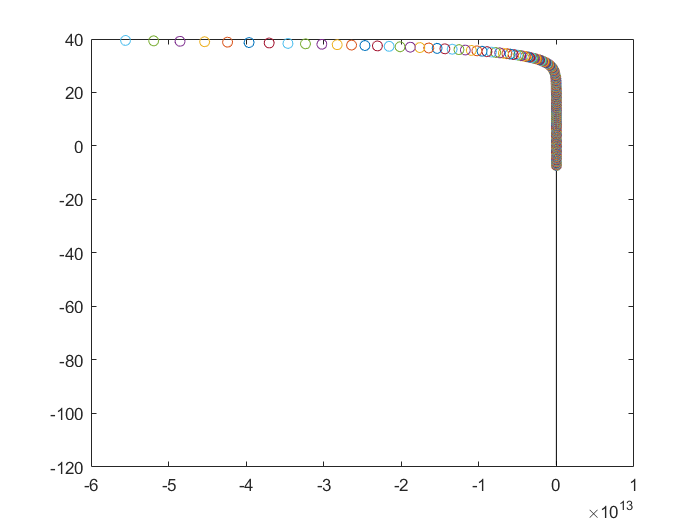

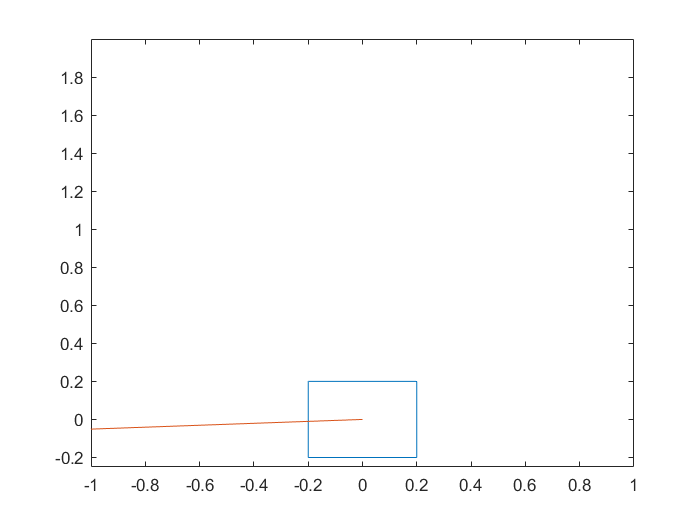


R = 10;

%Weight the slew rate - respect actuation bandwidths
Q = [10^2 0 0; 0 10^3 0;0 0 10 ];
N = 10;
Qbar = [];
Rbar = [];
Kbar = [];
refbar = [];
Gbar = [];
Sx = []; 
Sx2 = [];
Sr = [];
hr=[];
Sr2 = [];
Y = [0;0;0;0];
for ii = 1:N
    Qbar = blkdiag(Qbar,Q);
    Rbar = blkdiag(Rbar,R);
    Kbar = blkdiag(Kbar,K);
    
    Sx = blkdiag(Sx,Ad^(ii));
    Sx2 = blkdiag(Sx2,Cd*Ad^(ii-1));
    if ii==1
        hr = [Bd];
    else 
        hr = [Ad^(ii-1)*Bd hr];
    end
    
    Sr = [Sr;[hr  zeros(3,3*N -ii*3)]];
end
Z = zeros(3,3*N);
Sr2 =[Z;Sr(1:3*N-3,:)];
M = Kbar* (eye(3*N) - Sr2);
Gbar = M;
Nbar = Kbar*Sx2;
Fr = -2*Qbar*Sr;
Fx = 2*Sx'*Qbar*Sr - 2*Nbar'*Rbar*M;
H = 2*(Sr'*Qbar*Sr + M'*R*M);

F1 = -2*Qbar;
F2 = -2*Kbar'*Rbar * Kbar;

G = [-Gbar;Gbar];
W0 = ones(2*N,1)*12;
options = optimoptions('quadprog');
options.Display = 'none';
ii = 1;
T = 1000;
rlist = [];
theta_list = [];
output_list =[];

U = 0;
ref_V = 0;
ref_theta = 0;
ref_thetad = 0;
X1 = [0,0,0]';
X2 = [0;0];
global XY;
XY = readmatrix("Path_mpc.csv");
p_XY = XY(1,:);
dt = Ts;
p = [p_XY];
rateMPC = rateControl(5);
index = 0;
plot_xy = [];
plot_theta = [];
index = 0;

while ( index + N < 2222)
    X0 = X1;
    plot_theta = [plot_theta;X0(2)];
    psi = X2(1);
    refbar = [];
    X0bar = [];
    heading = [X0(1)*cos(psi),X0(1)*sin(psi)];
    
    p_XY = [X0(1)*cos(psi) + p_XY(1), X0(1)*sin(psi) + p_XY(2)];
    index = nearestNextPoint(p_XY,index,N);
    des_XY = XY(index,:);
    d_XY = (des_XY-p_XY);
    des_psi = atan2(-d_XY(2),d_XY(1));
    for kk = 1:N
        
        
        if (kk==1)
            ref_V =  norm(XY(index+1,:)- p_XY);
            
        else
            ref_V = norm(XY(index+kk+1,:) - XY(index+kk,:));
        end
        
        refbar = [refbar;-ref_V;ref_theta;ref_thetad];
        X0bar = [X0bar;X0];
    end
    f = refbar'*Fr + X0bar'*Fx;

    W = W0 + [-Nbar*X0bar;Nbar*X0bar];
    Z = quadprog(H,f,G,W,[],[],[],[],[],options);  %Here is the magic!
    
    rmpc = Z(1:3)  
    X1 = Ad*X0 + Bd*rmpc;
    
    err_psi = des_psi - X2(1);
    u_diff = -0.75*err_psi;
    X2 = A2*X2 + B2*u_diff;
    
    X2(1);
    p = [p;p_XY];
    
    ii = ii +1;
    theta = X1(2);
    
    
    plot(XY(:,1),XY(:,2),'k')
    figure(1);hold('on');             
    scatter(p_XY(1),p_XY(2)),hold('off');
    
    figure(2);hold('off');
    plot([0.2,0.2,-0.2,-0.2,0.2],[-0.2,0.2,0.2,-0.2,-0.2]);hold('on');
    plot([0,2*sin(theta)],[0,2*cos(theta)]);hold('off');
    xlim([-1,1]);
    ylim([-0.25,2]);
    drawnow()    
end


function next_index = nearestNextPoint(current_pose,index,N)
    global XY;
    next_index = index;
    n = size(XY,1) - N-1;
    dist = norm(current_pose - XY(index+1,:));
    for i = index+1 : n
        if(norm(current_pose - XY(i,:)) > dist)
            next_index = i-1;
            break;
        else
            dist = norm(current_pose - XY(i,:));
        end
    end
end
